# Exmanen primer parcial Robótica

Barajas Gaete Rodrigo Ainar

Definición de funciones

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Definición de la transformación homógenea general
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Modelado del robot Scara

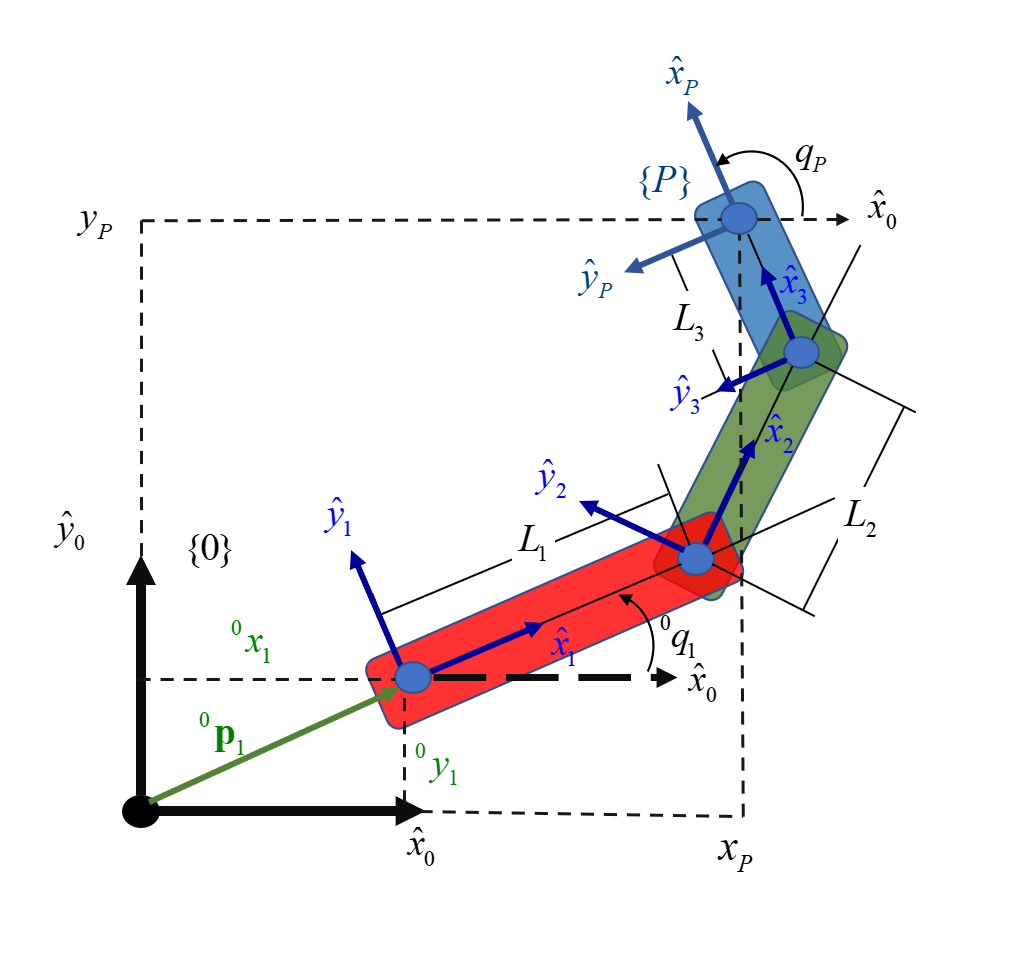

### Planteamiento del modelo cinemático de la posición

Partiendo de:


$${}^0\mathbf{T}_{P} ={}^0\mathbf{T}_{1}{}^1\mathbf{T}_{2}{}^0\mathbf{T}_{3}{}^3\mathbf{T}_{P} =\pmatrix{{}^0\mathbf{R}_P & {}^0\mathbf{p}_P \cr \mathbf{0}^T & 1  }$$


Donde 

- ${}^0\mathbf{T}_{1}$  :

syms x_O_1 y_O_1 theta_O_1 L_2 theta_1_2 L_3 theta_2_3 L_1

T_O_1 = Tij(x_O_1,y_O_1,0,0,0,theta_O_1)

$$T\_O\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

- ${}^1\mathbf{T}_{2}$: 

T_1_2 = Tij(L_1,0,0,0,0,theta_1_2)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0 & L_{1}\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

- ${}^2\mathbf{T}_{3
}$:

T_2_3 = Tij(L_2,0,0,0,0,theta_2_3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0 & L_{2}\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

- ${}^3\mathbf{T}_{P}$:

T_3_P = Tij(L_3,0,0,0,0,0)

$$T\_3\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{3}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Por lo tanto nuestra matriz general es la siguiente:

T_O_P = simplify(T_O_1*T_1_2*T_2_3*T_3_P)

$$T\_O\_P = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

Para el modelo cinemático de postura proponemos:

### 
$$\mathbf{F}={}^o\xi_{p} - {}^o\xi_{p}(q) = \mathbf{0}\Longrightarrow {}^o\xi_{p} = {}^o\xi_{p}(q)$$


Donde 


$$ {}^o\xi_{p}(q) = \pmatrix{{}^{o}\mathbf{p}_{P}\cr{}^{o}\mathbf{\theta}_{P}
}$$


Dado que obtivimos 

xi_O_P = [T_O_P(1,4);T_O_P(2,4);theta_O_1+theta_1_2+theta_2_3]

$$xi\_O\_P = \left(\begin{array}{c} x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \theta_{1,2}+\theta_{2,3}+\theta_{O,1} \end{array}\right)$$

var = htrans(xi_O_P)

$$var = \left(\begin{array}{c} \left\{ \begin{array}{cl} -\infty & \text{ if }x=0 \end{array}\right.\\ 0\\ 0 \end{array}\right)$$

### Modelo inverso de postura

Dado que el modelo directo de postura no es una matriz cuadrada, para obtener su inversa se propone **pseudoinversa de Moore-Penrose (por izquierda debido a que la matriz contiene más filas que columnas)**:


$$A^+ ={\left(A^T A\right)}^{-1} A^T$$


Calculando matriz traspuesta:

AT = transpose(xi_O_P);

Realizando: ${\left(A^T A\right)}^{-1}$

Atemporal = (AT*xi_O_P)^(-1);

Realizando: ${\left(A^T A\right)}^{-1} A^T$

inv_xi_O_P = Atemporal*transpose(xi_O_P)

$$inv\_xi\_O\_P = \begin{array}{l} \left(\begin{array}{ccc} \frac{x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)}{\sigma_{1}} & \frac{y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)}{\sigma_{1}} & \frac{\theta_{1,2}+\theta_{2,3}+\theta_{O,1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(y_{O,1}+L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)+L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\right)}^{2}+{\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)}^{2}+{\left(x_{O,1}+L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\right)}^{2} \end{array}$$

### Modelo cinemático directo de las velocidades

Partiendo del modelo de postura:

   
$${}^o\xi_{p} = {}^o\xi_{p}(q)$$
   

Aplicamos operador derivada total a ambos miembros del modelo:


$$\frac{d}{dt}{}^o\xi_{p} =\frac{d}{dt} {}^o\xi_{p}(q)$$
   

Desarrollando $\frac{d}{dt} {}^0\xi_{p}(q)$:

$\frac{d}{dt} {}^o\xi_{p}(q) = \frac{\partial}{\partial{}^o\theta_{1}}{}^o\xi_{p}(q) {}^o\dot\theta_{1}+\frac{\partial}{\partial{}^1\theta_{2}}{}^o\xi_{p}(q) {}^1\dot\theta_{2}+\frac{\partial}{\partial{}^2\theta_{3}}{}^o\xi_{p}(q) {}^2\dot\theta_{3}$...

... = $\left(\frac{\partial}{\partial{}\space^o\theta_{1}}{}^o\xi_{P}(q) \space\space\frac{\partial}{\partial\space{}^1\theta_{2}}{}^o\xi_{P}(q)\space\space\frac{\partial}{\partial\space{}^2\theta_{3}}{}^o\xi_{P}(q)\right)$ $\pmatrix{{}^{o}\dot{\theta}_{1} \cr {}^{1}\dot{\theta}_{2}\cr{}^{2}\dot{\theta}_{3}}$

De esta forma el modelo se puede representar de la siguiete forma:

### 
$${}^o\dot\xi_{P}=\mathbf{J}_{\theta}(q)\dot\mathbf{q}$$


Donde $\mathbf{J}_{\theta}(q)
$ es la siguiente matriz: 

syms J_theta

J_theta 

$$J\_theta = J_{\theta }$$

J_theta = jacobian(xi_O_P,[theta_O_1, theta_1_2,theta_2_3])

$$J\_theta = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{O,1}\right)-\sigma_{1} & -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-\sigma_{1} & -\sigma_{1}\\ L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2} & L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+\sigma_{2} & \sigma_{2}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

### Modelo cinemático inverso de las velocidades

Proponemos el siguiente modelo: 

### 
$$\dot\mathbf{q}={\mathbf{J}_{\theta}}^{-1}(q)\space{}^{o}\dot\xi_{P}$$


Dado que la matriz Jacobiana es una matriz cuadrada el modelo se simplifica.

Donde ${\mathbf{J}_{\theta}}^{-1}(q)$ es la siguiente matriz:

inv(J_theta)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & -\frac{\sin\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}} & \frac{L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{2}}\\ \frac{L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\cos\left(\theta_{O,1}\right)}{\sigma_{1}} & \frac{L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+L_{1}\,\sin\left(\theta_{O,1}\right)}{\sigma_{1}} & -\frac{L_{1}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)+L_{2}\,L_{3}\,\sigma_{4}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{2}\,L_{3}\,\sigma_{3}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)}{\sigma_{1}}\\ -\frac{\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & -\frac{\sin\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} & \frac{\sigma_{6}-\sigma_{5}+L_{3}\,\sigma_{4}\,\sin\left(\theta_{O,1}\right)-L_{3}\,\sigma_{3}\,\cos\left(\theta_{O,1}\right)}{\sigma_{6}-\sigma_{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{2}=L_{1}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{4}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{5}=L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)\,\cos\left(\theta_{O,1}\right)\\ \sigma_{6}=L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)\,\sin\left(\theta_{O,1}\right) \end{array}$$

Y donde ${}^{0}\dot\xi_{P}$ es el siguiente vector:


$$\pmatrix{{}^{o}\dot{x}_{P} \cr {}^{o}\dot{y}_{P}\cr{}^{o}\dot{\theta}_{P}}$$


### Modelo cinemático de las aceleraciones

Partiendo del modelo cinemático de velocidades (directo) :

   
$${}^o\dot\xi_{P}=\mathbf{J}_{\theta}(q)\dot\mathbf{q}$$


Aplicamos operador derivada total a ambos miembros del modelo:


$$\frac{d}{dt}{}^o\dot\xi_{p} =\frac{d}{dt}\left(\mathbf{J_{\theta}}(q)\dot\mathbf{q} \right)$$
   

        Desarrollando $\frac{d}{dt}\left(\mathbf{J_{\theta}}(q)\dot\mathbf{q} \right)$:

$\frac{d}{dt}\left(\mathbf{J_{\theta}}(q)\dot\mathbf{q} \right)= \dot\mathbf{J}_{\theta}(q,\dot{q})\dot\mathbf{q}+ \mathbf{J}_{\theta}(q)\ddot\mathbf{q}$...

Por lo tanto el modelo de aceleraciones directo es el siguiente:

### 
$${}^{o}\ddot\xi_{P}= \dot\mathbf{J}_{\theta}(q,\dot{q})\dot\mathbf{q}+ \mathbf{J}_{\theta}(q)\ddot\mathbf{q}$$


Donde:

-     
$$\ddot\mathbf{q}=\pmatrix{{}^{0}\ddot{\theta}_{1} \cr {}^{1}\ddot{\theta}_{2}\cr{}^{2}\ddot{\theta}_{3}}$$


- 
$$ \dot\mathbf{J}_{\theta}(q,\dot{q}) = \mathbf{H}_{\theta}(q,\dot{q}) $$


   Desarrollando  $ \mathbf{H}_{\theta}(q,\dot{q}) $ : 

syms theta_O_1 theta_1_2 theta_2_3 

H_l_1 = hessian(xi_O_P(1,:),[theta_O_1, theta_1_2, theta_2_3])

$$H\_l\_1 = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\cos\left(\theta_{O,1}\right)+\sigma_{2} & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & \sigma_{1} & \sigma_{2}\\ \sigma_{2} & \sigma_{2} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)+\sigma_{2}\\ \sigma_{2}=-L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

H_l_2 = hessian(xi_O_P(2,:),[theta_O_1, theta_1_2, theta_2_3])

$$H\_l\_2 = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{O,1}\right)+\sigma_{2} & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & \sigma_{1} & \sigma_{2}\\ \sigma_{2} & \sigma_{2} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)+\sigma_{2}\\ \sigma_{2}=-L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

H_l_3 = hessian(xi_O_P(3,:),[theta_O_1, theta_1_2, theta_2_3])

$$H\_l\_3 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

H_theta = [H_l_1(1,:);H_l_2(1,:);H_l_3(1,:)]

$$H\_theta = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\cos\left(\theta_{O,1}\right)-\sigma_{2} & -L_{2}\,\cos\left(\theta_{1,2}+\theta_{O,1}\right)-\sigma_{2} & -\sigma_{2}\\ -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-L_{1}\,\sin\left(\theta_{O,1}\right)-\sigma_{1} & -L_{2}\,\sin\left(\theta_{1,2}+\theta_{O,1}\right)-\sigma_{1} & -\sigma_{1}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right)\\ \sigma_{2}=L_{3}\,\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{O,1}\right) \end{array}$$

### Modelo cinemático inverso de las aceleraciones

Partiendo del modelo cinemático inverso de las velocidades, aplicamos derivada total a ambos miembros de la ecuación:


$$\frac{d}{dt}\dot\mathbf{q}=\frac{d}{dt}\left({\mathbf{J}_{\theta}}^{-1}(q)\space{}^{o}\dot\xi_{P}\right)$$


    Se aplica regla de la cadena en el miembro derecho


$$\frac{d}{dt}\left({\mathbf{J}_{\theta}}^{-1}(q)\space{}^{o}\dot\xi_{P}\right) = \frac{d}{dt}\left({\mathbf{J}_{\theta}}^{-1}(q)\right){}^{o}\dot\xi_{P}+{\mathbf{J}_{\theta}}^{-1}\frac{d}{dt}\left({}^{o} \dot\xi_{P}\right)=...
$$


            Desarrollando  $\frac{d}{dt}{\mathbf{J}_{\theta}}^{-1}(q)$ :


$$\frac{d}{dt}{\mathbf{J}_{\theta}}^{-1}(q) = \ddot{\mathbf{q}} = -\mathbf{J}_{\theta}^{-1}(q) \dot{\mathbf{J}}_{\theta}(q, \dot{q}) \mathbf{J}_{\theta}^{-1}(q) $$


Sustityuendo:


$$\ddot{\mathbf{q}} = -\mathbf{J}_{\theta}^{-1}(q) \dot{\mathbf{J}}_{\theta}(q, \dot{q}) \mathbf{J}_{\theta}^{-1}(q){}^o
\dot{\xi}_P + \mathbf{J}_{\theta}^{-1}(q) {}^o \ddot{\xi}_P$$


Simplificando con $\dot{\xi}_P = \mathbf{J}_{\theta}(q) \dot{\mathbf{q}}$ : 


$$\ddot{\mathbf{q}} = -\mathbf{J}_{\theta}^{-1}(q) \dot{\mathbf{J}}_{\theta}(q, \dot{q}) \dot{\mathbf{q}} + \mathbf{J}_{\theta}^{-1}(q){}^o \ddot{\xi}_P$$


### Modelo dinámico por ecuaciones de Eüler-Lagrange

Se emplearan las siguientes ecuaciones para el cálculo de la energía cinética:

### 
$$k_{i} = \frac{m_{i}}{2} \mathbf{v}_{C_{i}}^T \mathbf{v}_{C_{i}} + \frac{1}{2} \mathbf{\omega}_{C_{i}}^T \mathbf{I}_{C_{i}} \mathbf{\omega}_{C_{i}}


$$


syms x_1_C1 theta_dot_O_1

v_C1_C1 = [0;x_1_C1*theta_dot_O_1;0]

$$v\_C1\_C1 = \left(\begin{array}{c} 0\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\\ 0 \end{array}\right)$$


v_O_C1 = [-x_1_C1*sin(theta_O_1)*theta_dot_O_1;x_1_C1*cos(theta_O_1)*theta_dot_O_1;0]

$$v\_O\_C1 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

transpose(v_C1_C1)*v_C1_C1

$$ans = {{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}$$

simplify(transpose(v_O_C1)*v_O_C1)

$$ans = {{\dot{\theta }}_{O,1}}^{2}\,{x_{1,\mathrm{C1}}}^{2}$$

## Cálculo de la posición de los centros de masa

syms x_1_C1 x_2_C2 x_3_C3

T_1_C1 = Tij(x_1_C1,0,0,0,0,0)
T_O_C1 = T_O_1*T_1_C1

T_2_C2 = Tij(x_2_C2,0,0,0,0,0)
T_O_C2 = T_O_1*T_1_2*T_2_C2

T_3_C3 = Tij(x_3_C3,0,0,0,0,0)
T_O_C3 = T_O_1*T_1_2*T_2_3*T_3_C3


%Vectores de posición
p_O_C1 = [T_O_C1(1,4);T_O_C1(2,4);T_O_C1(3,4)]
p_O_C2 = simplify([T_O_C2(1,4);T_O_C2(2,4);T_O_C2(3,4)])

p_O_C3 = simplify([T_O_C3(1,4);T_O_C3(2,4);T_O_C3(3,4)])

## Cálculo de las velocidades

syms theta_dot_O_1 theta_dot_1_2 theta_dot_2_3

v_O_C1 = diff(p_O_C1,theta_O_1)*theta_dot_O_1+diff(p_O_C1,theta_1_2)*theta_dot_1_2+diff(p_O_C1,theta_2_3)*theta_dot_2_3
v_O_C2 = diff(p_O_C2,theta_O_1)*theta_dot_O_1+diff(p_O_C2,theta_1_2)*theta_dot_1_2+diff(p_O_C2,theta_2_3)*theta_dot_2_3
v_O_C3 = diff(p_O_C3,theta_O_1)*theta_dot_O_1+diff(p_O_C3,theta_1_2)*theta_dot_1_2+diff(p_O_C3,theta_2_3)*theta_dot_2_3

Cálculo de la velocidades angulares

syms omega_1_1 omega_2_2 omega_3_3
%Propagación para el primer cuerpo
omega_1_1
omega_O_O = [0;0;0]
n_1_1 = [0;0;1]
R_O_1 = [T_O_1(1,1),T_O_1(1,2),T_O_1(1,3);T_O_1(2,1),T_O_1(2,2),T_O_1(2,3);T_O_1(3,1),T_O_1(3,2),T_O_1(3,3)]
R_1_O = transpose(R_O_1)

%Ecuación de propagación
omega_1_1 = R_1_O*omega_O_O+n_1_1*theta_dot_O_1

%Propagación para el segundo cuerpo
omega_2_2
n_2_2 = [0;0;1]
R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(1,3);T_1_2(2,1),T_1_2(2,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)]
R_2_1 = transpose(R_1_2)

%Ecuación de propagación
omega_2_2 = R_2_1*omega_1_1+n_2_2*theta_dot_1_2

%Propagación para el tercer cuerpo
omega_3_3
n_3_3 = [0;0;1]
R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(1,3);T_2_3(2,1),T_2_3(2,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)]
R_3_2 = transpose(R_2_3)

%Ecuación de propagación
omega_3_3 = R_3_2*omega_2_2+n_3_3*theta_dot_2_3
v_O_C3

## Defición de los elementos de inercia 

syms g I_xx1 I_yy1 I_zz1 I_xx2 I_yy2 I_zz2 I_xx3 I_yy3 I_zz3
%vector de gravedad

g_v = [0;-g;0]

I_C1 = [I_xx1,0,0;0,I_yy1,0;0,0,I_zz1]
I_C2 = [I_xx2,0,0;0,I_yy2,0;0,0,I_zz2]
I_C3 = [I_xx3,0,0;0,I_yy3,0;0,0,I_zz3]

Cáculo del Lagrangeano

syms m_1 m_2 m_3
%energía cinética de cada uno de los cuerpos

k_1 = simplify((m_1/2)*transpose(v_O_C1)*v_O_C1+(1/2)*transpose(omega_1_1)*I_C1*omega_1_1)

k_2 = simplify((m_2/2)*transpose(v_O_C2)*v_O_C2+(1/2)*transpose(omega_2_2)*I_C2*omega_2_2)

k_3 = simplify((m_3/2)*transpose(v_O_C3)*v_O_C3+(1/2)*transpose(omega_3_3)*I_C3*omega_3_3)
% Cáclulo de la energía potencial de cada cuerpo

u_1 = -m_1*transpose(p_O_C1)*g_v
u_2 = -m_2*transpose(p_O_C2)*g_v
u_3 = -m_3*transpose(p_O_C3)*g_v

Cálculo del Lagrangeano


La = (k_1+k_2+k_3)-(u_1+u_2+u_3)

## Cálculo de los pares

syms theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3

D_theta1 = diff(La,theta_dot_O_1)

% Cálculo de relación

tao_1 = diff(D_theta1,theta_O_1)*theta_dot_O_1 + diff(D_theta1,theta_1_2)*theta_dot_1_2 + diff(D_theta1,theta_2_3)*theta_dot_2_3 + diff(D_theta1,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta1,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta1,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_O_1)

D_theta2 = diff(La,theta_dot_1_2)
tao_2 = diff(D_theta2,theta_O_1)*theta_dot_O_1 + diff(D_theta2,theta_1_2)*theta_dot_1_2 + diff(D_theta2,theta_2_3)*theta_dot_2_3 + diff(D_theta2,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta2,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta2,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_1_2)

D_theta3 = diff(La,theta_dot_2_3)
tao_3 = diff(D_theta3,theta_O_1)*theta_dot_O_1 + diff(D_theta3,theta_1_2)*theta_dot_1_2 + diff(D_theta3,theta_2_3)*theta_dot_2_3 + diff(D_theta3,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta3,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta3,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_2_3)

tao = [tao_1;tao_2;tao_3]

% Cálculo de la matriz de inercia

M1 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[1,0,0,0,0,0,0])
M2 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,1,0,0,0,0,0])
M3 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,1,0,0,0,0])

M_theta = collect([M1 M2 M3],[m_1,m_2,m_3])

Cálculo del vector de pares de

V_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,0])
G_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,0,0,0,g])

Cálculo del modelo  Dinámico inverso